%计算考虑化学作用后的双腔室二锁体系
clear all
syms e r o;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=2;


for l = 2:0.05:5
%计算锁死所占成分
    fun1 = @(x1) P(x1).^3.*P(l-x1).^2;
    V_lock = 2*integral(fun1,0,l);

%计算开放所占成分
    fun2 = @(x1) P(x1-l).^2.*P(2*l-x1);
    V_open = 2*integral(fun2,l,2*l);
    P_lock = V_lock/(V_lock + V_open)  %计算锁死所占比例
    Plock=[Plock,P_lock];
end

P_lock = 0.3854

P_lock = 0.8498

P_lock = 0.9546

P_lock = 0.9775

P_lock = 0.9839

P_lock = 0.9853

P_lock = 0.9843

P_lock = 0.9817

P_lock = 0.9776

P_lock = 0.9721

P_lock = 0.9654

P_lock = 0.9576

P_lock = 0.9492

P_lock = 0.9406

P_lock = 0.9322

P_lock = 0.9243

P_lock = 0.9171

P_lock = 0.9107

P_lock = 0.9051

P_lock = 0.9002

P_lock = 0.8960

P_lock = 0.8924

P_lock = 0.8892

P_lock = 0.8866

P_lock = 0.8842

P_lock = 0.8822

P_lock = 0.8805

P_lock = 0.8789

P_lock = 0.8776

P_lock = 0.8764

P_lock = 0.8753

P_lock = 0.8743

P_lock = 0.8735

P_lock = 0.8727

P_lock = 0.8720

P_lock = 0.8713

P_lock = 0.8707

P_lock = 0.8702

P_lock = 0.8696

P_lock = 0.8692

P_lock = 0.8687

P_lock = 0.8683

P_lock = 0.8679

P_lock = 0.8675

P_lock = 0.8671

P_lock = 0.8667

P_lock = 0.8664

P_lock = 0.8660

P_lock = 0.8657

P_lock = 0.8654

P_lock = 0.8651

P_lock = 0.8648

P_lock = 0.8645

P_lock = 0.8642

P_lock = 0.8639

P_lock = 0.8636

P_lock = 0.8633

P_lock = 0.8631

P_lock = 0.8628

P_lock = 0.8625

P_lock = 0.8623

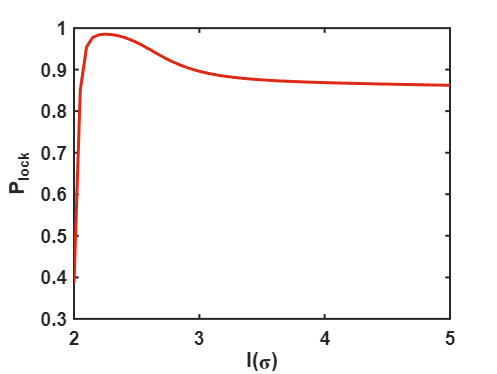



%画出锁死概率随l的变化
length=[2:0.05:5];
plot(length, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)


set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5500;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end
